% Define robot parameters
% link dimensions in m
L1 = 500 * 10^-3;
L2 = 250 * 10^-3;
L3 = 770 * 10^-3;
L4 = 70 * 10^-3;
L5 = 780 * 10^-3;
L6 = 215 * 10^-3;

% initial joint angles
%th_list = [0 -120 90 0 -90 0] * pi/180;   % Convert to radians
th_list = [0 0 0 0 0 0];

% target joint angles
th_list_2 = [45 -90 15 30 -60 45] * pi/180;

% home configuration
M = [
    1, 0, 0, L2+L3+L5+L6;
    0, 1, 0, 0;
    0, 0, 1, -L4;
    0, 0, 0, 1];

% axes of rotation
w1 = [0; 0; -1];
w2 = [0; 1; 0];
w3 = [0; 1; 0];
w4 = [-1; 0; 0];
w5 = [0; 0; 1];
w6 = [-1; 0; 0];
w_list = [w1, w2, w3, w4, w5, w6];

% screw axis position vectors, space frame
q1 = [0; 0; -L1];
q2 = [L2; 0; 0];
q3 = [L2+L3; 0; 0];
q4 = [L2+L3; 0; -L4];
q5 = [L2+L3+L5; 0; -L4];
q6 = [L2+L3+L5+L6; 0; -L4];
q_list = [q1, q2, q3, q4, q5, q6];

% velocity vectors
v_list = zeros([3, length(w_list)]);    % list of velocity vectors
% compute cross products of w and q. Add them to v_list
for i = 1:length(w_list)
    v = cross(-w_list(:, i), q_list(:, i));  % compute the cross product
    v_list(:, i) = v;   % add velocity vector element to v_list
end

% compute spatial screw list
screw_list = zeros([6, length(w_list)]);    % list of screws
% format the screw axes using w and v. Add them to screw_list
for i = 1:length(w_list)
    screw = [w_list(:, i ); v_list(:, i)];  % stack w(i) and v(i)
    screw_list(:, i) = screw;   % add screw axis to screw_list
end

% transform screw list to body frame
adj_M_inv = adj_transform(inv(M));      % adjacent of home configuration
body_screw_list = adj_M_inv * screw_list;       % transforms screw axis to body frame

% transform q's to body frame
q_list_h = [q_list; ones(1, length(q_list))];  % homogeneous form
body_q_list_h = M\q_list_h;  % T_bs * q_s = q_b
body_q_list = body_q_list_h(1:3, :);

Compute Inverse Kinematics

T_d = FK_space(M, screw_list, th_list_2, q_list, false);  % Desired config

% Numerical algorithm, no RR
[th_d_NA, thVelList, th_d_NA_array] = J_inverse_kinematics(M, body_screw_list, th_list, body_q_list, T_d, false);


% Numerical algorithm, with RR
[th_d_NA_RR, thVelList_RR, th_d_NA_RR_array] = J_inverse_kinematics(M, body_screw_list, th_list, body_q_list, T_d, true);


% Jacobian transpose
[th_d_JT, th_d_JT_array] = J_transpose_kinematics(M, body_screw_list, th_list, body_q_list, T_d);

Plot Robot Motion - Numerical, no RR

loops_NA = size(th_d_NA_array, 1);
fig = figure('Position', [50 50 1200 700]);
Mov_NA(loops_NA) = struct('cdata',[],'colormap',[]);
fig.Visible = 'off';

for i = 1:loops_NA % Create a frame for each iteration
    J_s = J_space(screw_list, th_d_NA_array(i, :));

    subplot(2, 2, 1);
    T_s = FK_space(M, screw_list, th_d_NA_array(i, :), q_list, true);
    title("Robot Position");

    subplot(2, 2, 3);
    ellipsoid_plot_linear(J_s, T_s);
    title("Linear Manipulability");

    subplot(2, 2, 4);
    ellipsoid_plot_angular(J_s, T_s);
    title("Angular Manipulability");
    
    % Annotate graph
    ann_iter = ['Iteration: ', num2str(i)];
    ann_cond = ['Condition: ', num2str(J_condition(J_s))];
    ann_iso = ['Isotropy: ', num2str(J_isotropy(J_s))];

    annotation('textbox', [.65 .8 0 0], 'String', ann_iter, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);
    annotation('textbox', [.65 .75 0 0], 'String', ann_cond, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);
    annotation('textbox', [.65 .7 0 0], 'String', ann_iso, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);

    drawnow

    if i == 1
        fig.Visible = 'on';
        pause;
        fig.Visible = 'off';
    end

    Mov_NA(i) = getframe(fig);
    clf
end

% 5 seconds target video length
% Don't exceed 24 fps
fps_NA = min(floor(loops_NA / 5), 24);

Plot Robot Motion - Numerical, with RR

loops_NA_RR = size(th_d_NA_RR_array, 1);
fig = figure('Position', [50 50 1200 700]);
Mov_NA_RR(loops_NA_RR) = struct('cdata',[],'colormap',[]);
fig.Visible = 'off';

for i = 1:loops_NA_RR % Create a frame for each iteration
    J_s = J_space(screw_list, th_d_NA_RR_array(i, :));

    subplot(2, 2, 1);
    T_s = FK_space(M, screw_list, th_d_NA_RR_array(i, :), q_list, true);
    title("Robot Position");

    subplot(2, 2, 3);
    ellipsoid_plot_linear(J_s, T_s);
    title("Linear Manipulability");

    subplot(2, 2, 4);
    ellipsoid_plot_angular(J_s, T_s);
    title("Angular Manipulability");
    
    % Annotate graph
    ann_iter = ['Iteration: ', num2str(i)];
    ann_cond = ['Condition: ', num2str(J_condition(J_s))];
    ann_iso = ['Isotropy: ', num2str(J_isotropy(J_s))];

    annotation('textbox', [.65 .8 0 0], 'String', ann_iter, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);
    annotation('textbox', [.65 .75 0 0], 'String', ann_cond, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);
    annotation('textbox', [.65 .7 0 0], 'String', ann_iso, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);

    drawnow

    if i == 1
        fig.Visible = 'on';
        pause;
        fig.Visible = 'off';
    end

    Mov_NA_RR(i) = getframe(fig);
    clf
end

% 5 seconds target video length
% Don't exceed 24 fps
fps_NA_RR = min(floor(loops_NA_RR / 5), 24);

Plot Robot Motion - Jacobian Transpose

loops_JT = size(th_d_JT_array, 1);
fig = figure('Position', [50 50 1200 700]);
Mov_JT(loops_JT) = struct('cdata',[],'colormap',[]);
fig.Visible = 'off';

for i = 1:loops_JT % Create a frame for each iteration
    fprintf("Iteration %d of %d\n", i, loops_JT)
    J_s = J_space(screw_list, th_d_JT_array(i, :));

    subplot(2, 2, 1);
    T_s = FK_space(M, screw_list, th_d_JT_array(i, :), q_list, true);
    title("Robot Position");

    subplot(2, 2, 3);
    ellipsoid_plot_linear(J_s, T_s);
    title("Linear Manipulability");

    subplot(2, 2, 4);
    ellipsoid_plot_angular(J_s, T_s);
    title("Angular Manipulability");

    % Annotate graph
    ann_iter = ['Iteration: ', num2str(i)];
    ann_cond = ['Condition: ', num2str(J_condition(J_s))];
    ann_iso = ['Isotropy: ', num2str(J_isotropy(J_s))];

    annotation('textbox', [.65 .8 0 0], 'String', ann_iter, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);
    annotation('textbox', [.65 .75 0 0], 'String', ann_cond, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);
    annotation('textbox', [.65 .7 0 0], 'String', ann_iso, 'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 18);

    drawnow

    if i == 1
        fig.Visible = 'on';
        pause;
        fig.Visible = 'off';
    end

    Mov_JT(i) = getframe(fig);
    clf
end

Iteration 1 of 570
Iteration 2 of 570
Iteration 3 of 570



% This video will be pretty long regardless
fps_JT = 24;

Play Movies

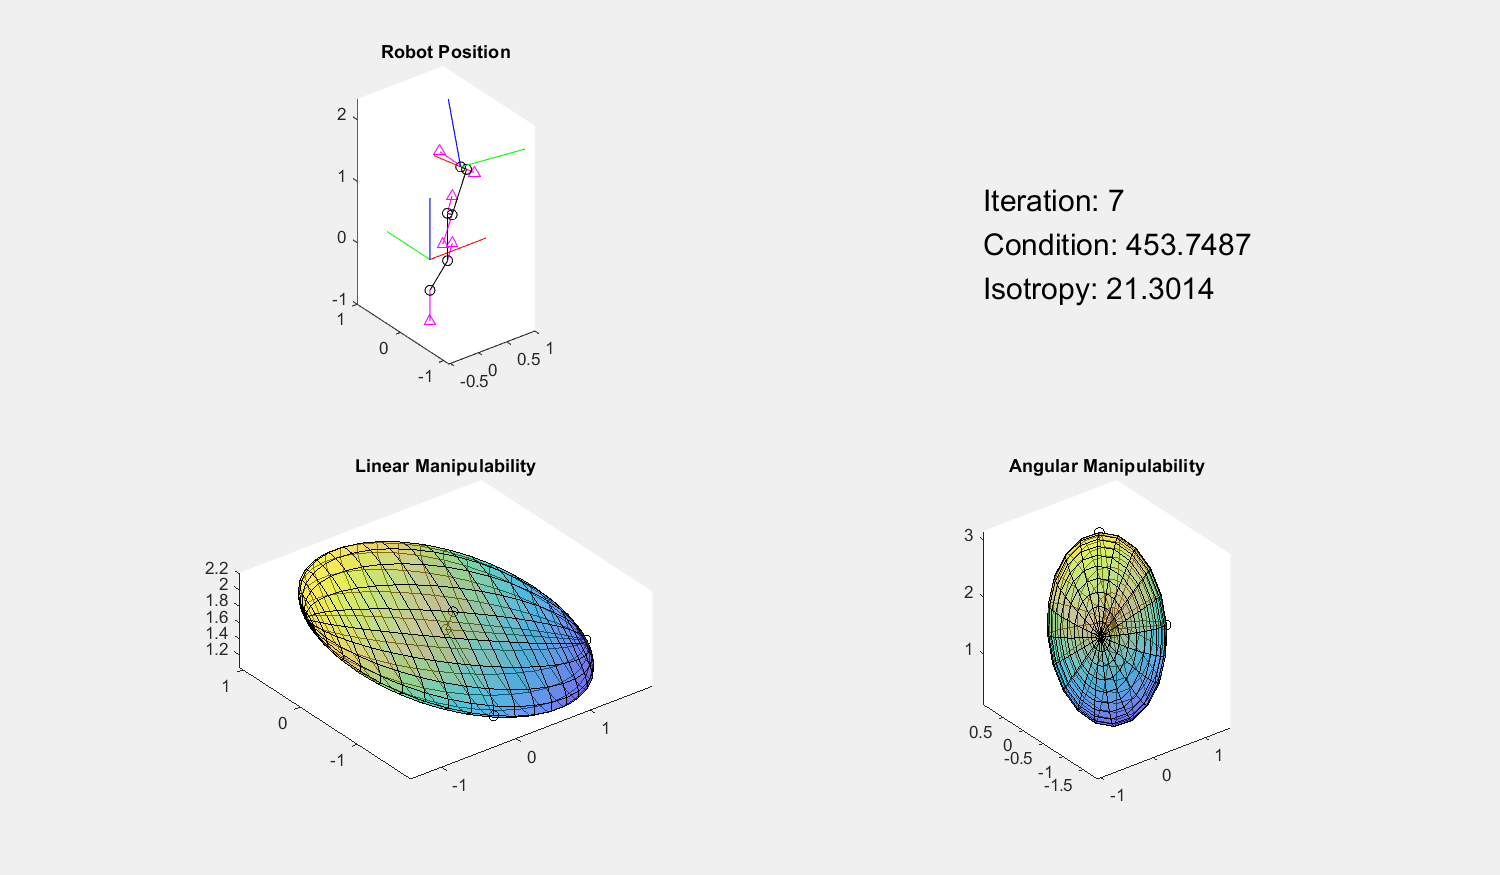

% Numerical, no RR
fig = figure('Position', [50 50 1200 700]);
fig.Visible = 'on';
movie(fig, Mov_NA, 1, fps_NA);

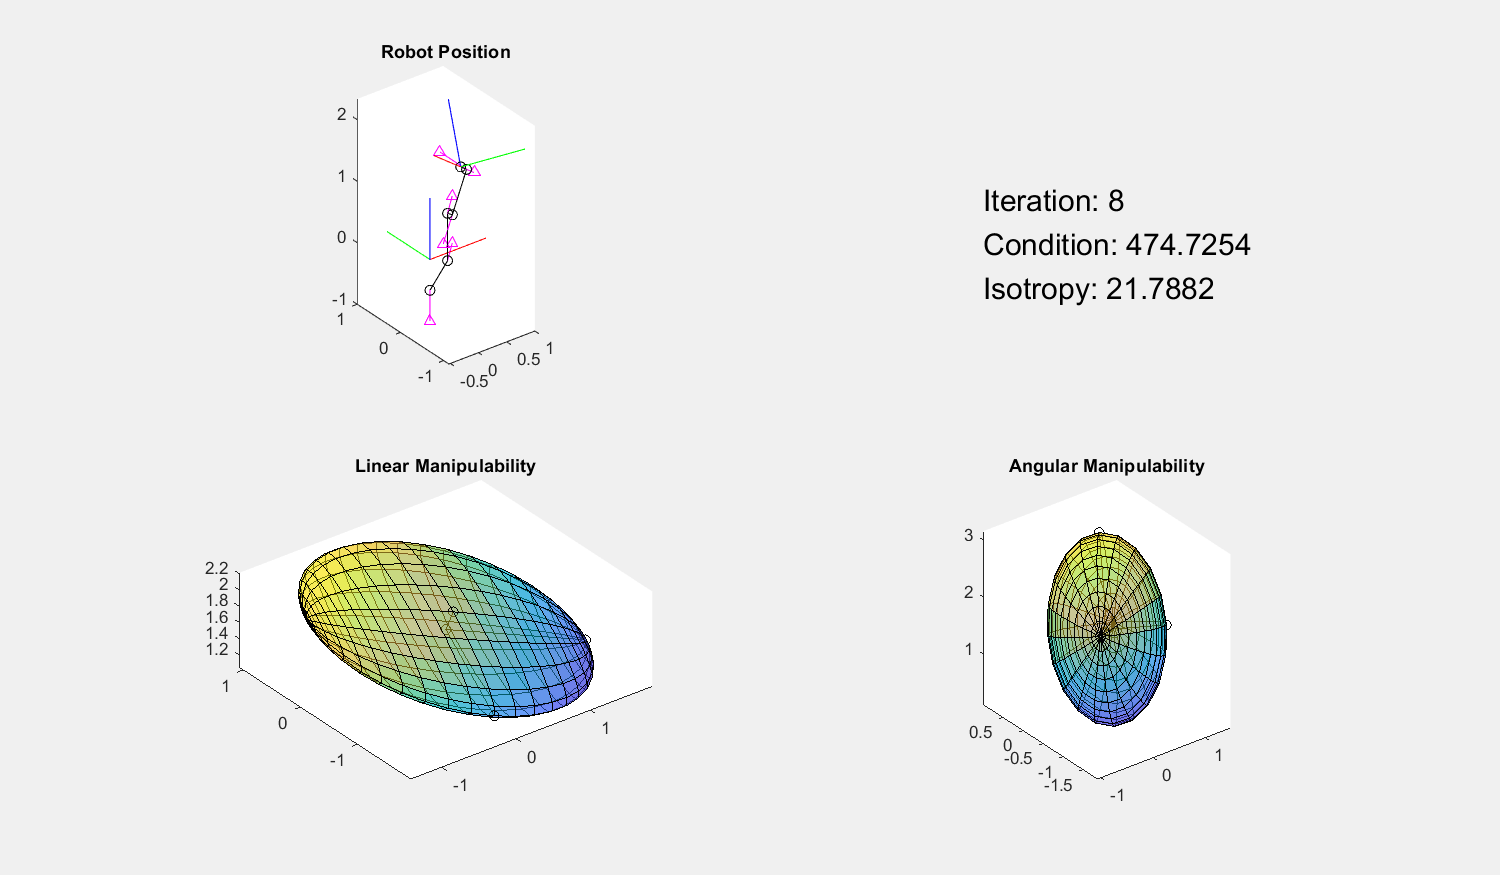

% Numerical, with RR
fig = figure('Position', [50 50 1200 700]);
fig.Visible = 'on';
movie(fig, Mov_NA_RR, 1, fps_NA_RR);

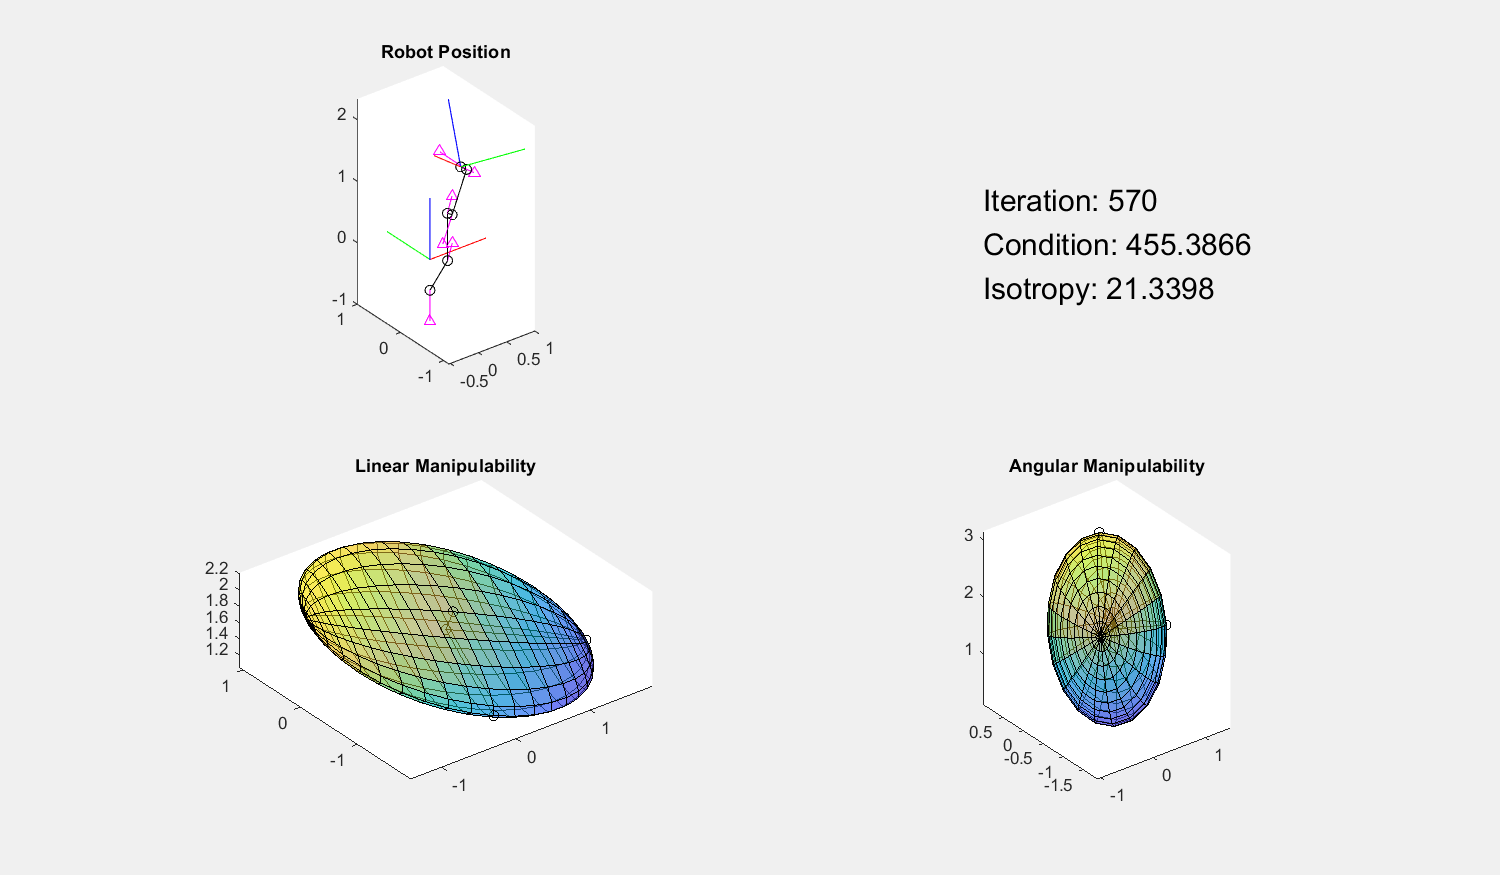

fig = figure('Position', [50 50 1200 700]);
fig.Visible = 'on';
movie(fig, Mov_JT_1, 1, 60);

Save as .avi files

v_NA = VideoWriter("mov_NA.avi");
v_NA.FrameRate = fps_NA;
open(v_NA);
writeVideo(v_NA, Mov_NA);
close(v_NA)

v_JT = VideoWriter("mov_JT.avi");
v_JT.FrameRate = 60;
open(v_JT);
writeVideo(v_JT, Mov_JT_1);
close(v_JT)